A = [-1 -0.5 ; 1 0];
B = [0.5 ; 0];
C = [1 0];
D = 0;
t = [0:0.05:10];
Te = 0.05;

G0 = c2d(ss(A,B,C,D), Te, 'zoh');

p = pole(G0)

p =    0.9750 + 0.0244i
   0.9750 - 0.0244i


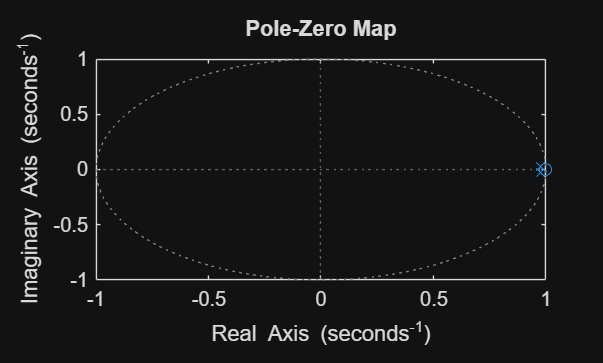

pzmap(G0)


[mag, ph, w] = dbode(G0.A, G0.B, G0.C, G0.D, Te);
[Mr k] = max(mag);
wr = w(k);
wrdB = 20*log10(wr);

n=1;
while 20*log10(mag(n)) > -3
    n = n+1;
end
banda = w(n);

disp("Vf de rezonanta = " + wr)

Vf de rezonanta = 0.66962


disp("Vf de rezonanta (dB) = " + wrdB)

Vf de rezonanta (dB) = -3.4834


disp("Largimea de banda = " + banda)

Largimea de banda = 0.01
